## Projectile trajectory

format short
g = 10;
%Vyjádřeno ze 2 rovnic a dosazeno za t (sin/cos = tan)
h = @(x,theta0,v0) tan(theta0).* x - g.*x.^2/(2.*(v0.*cos(theta0)).^2);

v0 = 100;
x = 50;
y = 80;
f = @(theta0) h(x,theta0,v0) - y;

%Choose first iteration angle 90deg - 0.01
theta = pi/2-0.01;
error=0.0001;

[theta,num] = newton_method(f,theta,error);

x_prev = 1.5608

ans = 0.0038

x_prev = 1.5570

ans = 0.0044

x_prev = 1.5526

ans = 0.0042

x_prev = 1.5484

ans = 0.0028

x_prev = 1.5456

ans = 8.7607e-04

x_prev = 1.5448

ans = 6.6810e-05

num

num = 6

theta

theta = 1.5447

rad2deg(theta)

ans = 88.5045

round(theta*360/(2*pi),2)

ans = 88.5000

plot(0:x,h(0:x,theta,v0))
xx = linspace(0,x,100)

xx =          0    0.5051    1.0101    1.5152    2.0202    2.5253    3.0303    3.5354    4.0404    4.5455    5.0505    5.5556    6.0606    6.5657    7.0707    7.5758    8.0808    8.5859    9.0909    9.5960   10.1010   10.6061   11.1111   11.6162   12.1212   12.6263   13.1313   13.6364   14.1414   14.6465   15.1515   15.6566   16.1616   16.6667   17.1717   17.6768   18.1818   18.6869   19.1919   19.6970   20.2020   20.7071   21.2121   21.7172   22.2222   22.7273   23.2323   23.7374   24.2424   24.7475


yy = linspace(0,y,100)

yy =          0    0.8081    1.6162    2.4242    3.2323    4.0404    4.8485    5.6566    6.4646    7.2727    8.0808    8.8889    9.6970   10.5051   11.3131   12.1212   12.9293   13.7374   14.5455   15.3535   16.1616   16.9697   17.7778   18.5859   19.3939   20.2020   21.0101   21.8182   22.6263   23.4343   24.2424   25.0505   25.8586   26.6667   27.4747   28.2828   29.0909   29.8990   30.7071   31.5152   32.3232   33.1313   33.9394   34.7475   35.5556   36.3636   37.1717   37.9798   38.7879   39.5960


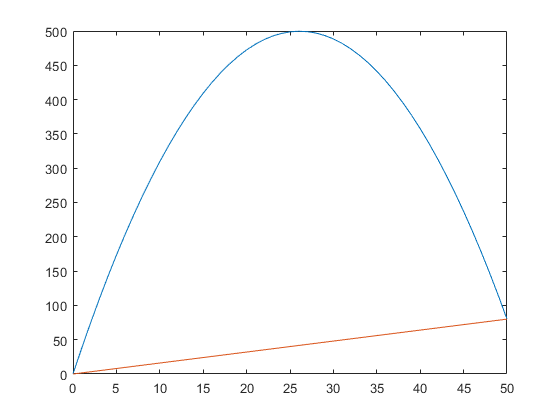

hold on
plot(xx,yy)
hold off

%Choose first iteration angle 30deg
theta = pi/6;
error=0.0001;

[theta,num] = newton_method(f,theta,error);

x_prev = 0.5236

ans = -0.8155

x_prev = 1.3391

ans = 0.1448

x_prev = 1.1943

ans = 0.1152

x_prev = 1.0791

ans = 0.0381

x_prev = 1.0410

ans = 0.0027

x_prev = 1.0383

ans = 1.1542e-05

num

num = 6

round(theta*360/(2*pi),2)

ans = 59.4900

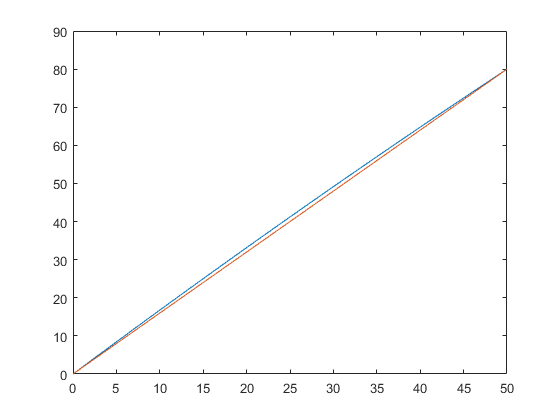

plot(0:x,h(0:x,theta,v0))
hold on
plot(xx,yy)
hold off

function [x,num] = newton_method(f,x,error)
%Newton method
x_prev=Inf;
df=derivative(f);
num=0;
while abs(x-x_prev)>error
    x_prev=x
    x=x-f(x)/df(x);
    num=num+1;
end
end